%clear; close; clc;

% optimization parameters
number_of_particles = 30000; % number of particles to use in swarm
number_of_dimentions = 8; % how many design vars
max_iterations = 100; % maximum number of itterations to use
inertia = .5; % inertial weight
c_1 = 1.5; % coginitive coefficient (infulence of particels best position)
c_2 = 1.5; % social coefficient (influence of gobal best position)
epsilon_1 = 1e-6; % unconstrained tolerance
epochs = 100;
fails_per_epoch = 100;
% known solution
%x_valid = [0; 0.0442; 0.0088; 0.0381; 0.0004; 0.0199; 0.0016; 0.0146];
%x_valid = [1.2; 0.0442; 0.0088; 0.0381; 0.0004; 0.0199; 0.0016; 0.0146];
%x_valid = [1.2;  0.8; 0.08; 0.08; 0.05; 0.05; 0.05; 0.05];
%x_valid = [1;  1; 1; 1; 0.05; 0.05; 0.05; 0.05];
x_valid = zeros(8,1) + rand([8,1])*1e-1+1e-12

x_valid =     0.0484
    0.0406
    0.0540
    0.0755
    0.0671
    0.0697
    0.0260
    0.0915



% initialize the optimization
x_lower = min(x_valid -.01, 0); %- [1; 1; 1; 1; .01; .01; .01; .01;]
x_upper = x_valid+.1;

% x_lower = zeros([8,1])+1e-12;
% x_upper = ones([8,1]);

f_bests = ones([1,epochs])*Inf;
x_bests = ones([length(x),epochs])*Inf;
is_feasible = [];

for epoch = 1:epochs
    % start the swarm in a random (relatively feasible) location
    x_valid = zeros(8,1) + rand([8,1])*1e-1+1e-12;
    x_lower = min(x_valid -.01, 0); %- [1; 1; 1; 1; .01; .01; .01; .01;]
    x_upper = x_valid+.1;
    
    % optimization prosses
    for i = 1:fails_per_epoch % it will take us a few attempts to even get a valid solution
        [global_best, global_best_fitness] = particle_swarm_optimization(@(x) objective_function(x), number_of_dimentions, number_of_particles, max_iterations, inertia, c_1, c_2, x_lower, x_upper, true);
        if all(wingbox_constraints(global_best) <= epsilon_1) % if it is a valid solution
            break; % stop
        end
    end
    disp('Global best position:');
    disp(global_best);
    disp('Global best fitness:');
    disp(global_best_fitness);
    disp('Is feasible: ');
    disp(all(wingbox_constraints(global_best) <= epsilon_1));

    f_bests(epoch) = global_best_fitness;
    x_bests(:,epoch) = global_best;
    %is_feasible(epoch) = wingbox_constraints(x_bests(:,epoch)) % compute the feasibility
end

Global best position:


    0.3889
    0.0175
    0.0292
    0.0979
    0.0288
    0.0906
    0.0747
    0.1006



Global best fitness:


    3.1744



Is feasible: 


   1



Global best position:


    0.4825
    0.0633
    0.1273
    0.1007
    0.0426
    0.0965
    0.0643
    0.0819



Global best fitness:


    3.3913



Is feasible: 


   1



Global best position:


    0.7159
    0.0629
    0.1164
    0.5098
    0.0823
    0.1207
    0.0095
    0.0378



Global best fitness:


    3.5961



Is feasible: 


   1



Global best position:


    0.0376
    0.0408
    0.0212
    0.1582
    0.1036
    0.0102
    0.0864
    0.0438



Global best fitness:


    3.8576



Is feasible: 


   1



Global best position:


    0.4436
    0.0187
    0.0065
    0.1842
    0.0301
    0.0488
    0.0520
    0.0563



Global best fitness:


    2.5483



Is feasible: 


   1



Global best position:


    0.3116
    0.0999
    0.1525
    0.0450
    0.0699
    0.1400
    0.0583
    0.1241



Global best fitness:


    3.9669



Is feasible: 


   1



Global best position:


    0.1152
    0.0979
    0.0882
    0.1005
    0.0742
    0.0636
    0.0489
    0.0787



Global best fitness:


    3.1876



Is feasible: 


   1



Global best position:


    0.0894
    0.0149
    0.0995
    0.0579
    0.0670
    0.0665
    0.0504
    0.1392



Global best fitness:


    3.2890



Is feasible: 


   1



Global best position:


    0.5818
    0.0153
    0.1348
    0.0865
    0.0223
    0.1755
    0.1013
    0.0176



Global best fitness:


    3.6113



Is feasible: 


   1



Global best position:


    0.4072
    0.0403
    0.0112
    0.1026
    0.0422
    0.1032
    0.0106
    0.5811



Global best fitness:


    5.0116



Is feasible: 


   1



Global best position:


    0.8150
    0.0916
    0.0048
    0.1099
    0.1835
    0.1018
    0.0434
    0.1270



Global best fitness:


    6.0167



Is feasible: 


   1



Global best position:


    0.5958
    0.0102
    0.0748
    0.0248
    0.0796
    0.1245
    0.0637
    0.0810



Global best fitness:


    4.0436



Is feasible: 


   1



Global best position:


    0.0635
    0.0267
    0.0503
    0.0141
    0.0830
    0.0666
    0.0723
    0.0269



Global best fitness:


    3.2250



Is feasible: 


   1



Global best position:


    0.6934
    0.1508
    0.0012
    0.0675
    0.0695
    0.0951
    0.0277
    0.4351



Global best fitness:


    5.3123



Is feasible: 


   1



Global best position:


    0.3432
    0.1582
    0.0575
    0.1046
    0.0666
    0.0075
    0.0986
    0.0283



Global best fitness:


    3.7308



Is feasible: 


   1



Global best position:


    0.5165
    0.0730
    0.0071
    0.0126
    0.0441
    0.0074
    0.0727
    0.0741



Global best fitness:


    3.0831



Is feasible: 


   1



Global best position:


    0.2811
    0.0459
    0.0463
    0.0601
    0.0433
    0.0676
    0.0758
    0.0766



Global best fitness:


    3.1459



Is feasible: 


   1



Global best position:


    0.1016
    0.1099
    0.1142
    0.0958
    0.0787
    0.0982
    0.1397
    0.0698



Global best fitness:


    4.9237



Is feasible: 


   1



Global best position:


    0.3120
    0.0782
    0.0188
    0.0565
    0.0634
    0.0095
    0.0955
    0.0220



Global best fitness:


    3.3926



Is feasible: 


   1



Global best position:


    0.1397
    0.0236
    0.1063
    0.0902
    0.0558
    0.0376
    0.0423
    0.1946



Global best fitness:


    3.2674



Is feasible: 


   1



Global best position:


    0.6234
    0.1262
    0.0599
    0.0759
    0.0577
    0.0443
    0.1585
    0.0166



Global best fitness:


    4.8874



Is feasible: 


   1



Global best position:


    0.2973
    0.0397
    0.0072
    0.0522
    0.0434
    0.1257
    0.0603
    0.1019



Global best fitness:


    3.1576



Is feasible: 


   1



Global best position:


    0.8212
    0.0788
    0.0897
    0.2904
    0.0974
    0.0329
    0.0166
    0.2200



Global best fitness:


    4.5983



Is feasible: 


   1



Global best position:


    0.2382
    0.0586
    0.0855
         0
    0.0478
    0.0501
    0.0754
    0.0283



Global best fitness:


    2.8463



Is feasible: 


   1



Global best position:


    0.0905
    0.0390
    0.0503
    0.0530
    0.0927
    0.0383
    0.0857
    0.0223



Global best fitness:


    3.5948



Is feasible: 


   1



Global best position:


    0.0692
    0.1563
    0.0591
    0.0600
    0.0744
    0.1304
    0.1121
    0.0967



Global best fitness:


    4.5396



Is feasible: 


   1



Global best position:


    0.6628
    0.1731
    0.0709
    0.1218
    0.1184
    0.0295
    0.0487
    0.1199



Global best fitness:


    4.7108



Is feasible: 


   1



Global best position:


    0.5007
    0.0562
    0.0474
    0.1247
    0.0440
    0.0523
    0.0567
    0.0551



Global best fitness:


    2.9535



Is feasible: 


   1



Global best position:


    0.1466
    0.0173
    0.0288
    0.0247
    0.0736
    0.1404
    0.0620
    0.0284



Global best fitness:


    3.1796



Is feasible: 


   1



Global best position:


    0.1373
    0.1320
    0.0711
    0.1690
    0.0698
    0.0602
    0.0712
    0.1047



Global best fitness:


    3.7395



Is feasible: 


   1



Global best position:


    0.3030
    0.0138
    0.0422
    0.0827
    0.0370
    0.0132
    0.0698
    0.1151



Global best fitness:


    2.9838



Is feasible: 


   1



Global best position:


    0.1201
    0.0406
    0.0619
    0.1063
    0.1480
    0.0099
    0.0426
    0.1026



Global best fitness:


    4.2693



Is feasible: 


   1



Global best position:


    0.1655
    0.1100
    0.1005
    0.0106
    0.0517
    0.1162
    0.0549
    0.1141



Global best fitness:


    3.2390



Is feasible: 


   1



Global best position:


    0.3960
    0.0472
    0.0827
    0.0947
    0.0358
    0.0565
    0.0794
    0.0413



Global best fitness:


    3.0328



Is feasible: 


   1



Global best position:


    0.4916
    0.0249
    0.0834
    0.0260
    0.0816
    0.1186
    0.0546
    0.1359



Global best fitness:


    4.1260



Is feasible: 


   1



Global best position:


    0.7656
    0.0936
    0.1451
    0.1182
    0.0185
    0.0364
    0.0575
    0.1324



Global best fitness:


    3.2911



Is feasible: 


   1



Global best position:


    0.7016
    0.0563
    0.0180
    0.0672
    0.0391
    0.0528
    0.0671
    0.0704



Global best fitness:


    3.2480



Is feasible: 


   1



Global best position:


    0.1471
    0.0772
    0.0431
    0.0924
    0.0891
    0.0601
    0.0572
    0.0189



Global best fitness:


    3.2101



Is feasible: 


   1



Global best position:


    0.1548
    0.0198
    0.0544
    0.1198
    0.0655
    0.0273
    0.0676
    0.1141



Global best fitness:


    3.3916



Is feasible: 


   1



Global best position:


    0.7318
    0.0035
    0.0267
    0.0439
    0.0385
    0.0319
    0.0899
    0.0166



Global best fitness:


    3.2373



Is feasible: 


   1



Global best position:


    0.0018
    0.0014
    0.0268
    0.0602
    0.0987
    0.1831
    0.0592
    0.0864



Global best fitness:


    3.8960



Is feasible: 


   1



Global best position:


    0.7780
    0.0835
    0.1241
    0.0988
    0.0035
    0.1280
    0.1290
    0.1039



Global best fitness:


    4.3575



Is feasible: 


   1



Global best position:


    0.0723
    0.0897
    0.1588
    0.0640
    0.0791
    0.1163
    0.0828
    0.0752



Global best fitness:


    3.9896



Is feasible: 


   1



Global best position:


    0.9262
    0.0307
    0.1874
    0.0255
    0.1052
    0.0578
    0.0654
    0.0617



Global best fitness:


    4.6769



Is feasible: 


   1



Global best position:


    0.3873
    0.0409
    0.0360
    0.0020
    0.1097
    0.0991
    0.0655
    0.0387



Global best fitness:


    4.0520



Is feasible: 


   1



Global best position:


    0.3473
    0.0361
    0.0048
    0.1340
    0.0402
    0.0113
    0.1223
    0.0402



Global best fitness:


    3.6162



Is feasible: 


   1



Global best position:


    0.8417
    0.1102
    0.0665
    0.0073
    0.0380
    0.0158
    0.0772
    0.0812



Global best fitness:


    3.5332



Is feasible: 


   1



Global best position:


    0.5557
    0.0758
    0.1177
    0.1524
    0.0202
    0.0125
    0.0953
    0.0217



Global best fitness:


    3.0744



Is feasible: 


   1



Global best position:


    0.2611
    0.0277
    0.1049
    0.0684
    0.0616
    0.0750
    0.0572
    0.0668



Global best fitness:


    3.1402



Is feasible: 


   1



Global best position:


    0.4537
    0.0396
    0.0247
    0.1220
    0.0890
    0.0124
    0.1074
    0.0920



Global best fitness:


    4.6202



Is feasible: 


   1



Global best position:


    0.0576
    0.0449
    0.0659
    0.0490
    0.0809
    0.1564
    0.0557
    0.0764



Global best fitness:


    3.5116



Is feasible: 


   1



Global best position:


    0.5694
    0.1086
    0.0652
    0.1892
    0.0245
    0.0972
    0.0473
    0.0762



Global best fitness:


    2.9056



Is feasible: 


   1



Global best position:


    0.2844
    0.0912
    0.0168
    0.0955
    0.1674
    0.0549
    0.0613
    0.0213



Global best fitness:


    4.7857



Is feasible: 


   1



Global best position:


    0.6176
    0.0201
    0.0720
    0.1811
    0.0160
    0.1341
    0.1029
    0.0240



Global best fitness:


    3.5081



Is feasible: 


   1



Global best position:


    0.0639
    0.0838
    0.0590
    0.0726
    0.0987
    0.0471
    0.0450
    0.0935



Global best fitness:


    3.4577



Is feasible: 


   1



Global best position:


    0.4118
    0.0786
    0.1587
    0.0429
    0.0657
    0.0155
    0.0872
    0.0332



Global best fitness:


    3.5957



Is feasible: 


   1



Global best position:


    0.5299
    0.0015
    0.1109
    0.0008
    0.0994
    0.1034
    0.0657
    0.0671



Global best fitness:


    4.2234



Is feasible: 


   1



Global best position:


    0.9811
    0.0477
    0.0341
    0.0386
    0.0370
    0.0061
    0.0832
    0.0254



Global best fitness:


    3.3601



Is feasible: 


   1



Global best position:


    0.3803
    0.0822
    0.0779
    0.0323
    0.1279
    0.1038
    0.0619
    0.0216



Global best fitness:


    4.3374



Is feasible: 


   1



Global best position:


    0.1704
    0.1243
    0.0935
    0.0023
    0.1481
    0.0092
    0.0714
    0.0154



Global best fitness:


    4.3508



Is feasible: 


   1



Global best position:


    0.2711
    0.0249
    0.0469
    0.1770
    0.0540
    0.0904
    0.0307
    0.1844



Global best fitness:


    3.2995



Is feasible: 


   1



Global best position:


    0.1668
    0.0145
    0.0939
    0.0208
    0.1294
    0.0622
    0.0582
    0.0610



Global best fitness:


    4.1119



Is feasible: 


   1



Global best position:


    0.0735
    0.1070
    0.0143
    0.0193
    0.0755
    0.0718
    0.0539
    0.1288



Global best fitness:


    3.4120



Is feasible: 


   1



Global best position:


    0.4705
    0.0142
    0.0094
    0.0718
    0.0193
    0.1338
    0.0519
    0.2066



Global best fitness:


    3.3590



Is feasible: 


   1



Global best position:


    0.3545
         0
    0.0835
         0
    0.0480
    0.2426
    0.1202
    0.0170



Global best fitness:


    4.2128



Is feasible: 


   1



Global best position:


    0.2686
    0.1248
    0.0303
    0.0997
    0.1005
    0.0244
    0.0502
    0.0442



Global best fitness:


    3.4831



Is feasible: 


   1



Global best position:


    0.2595
    0.0965
    0.0389
    0.1823
    0.0661
    0.1249
    0.0359
    0.0939



Global best fitness:


    3.2658



Is feasible: 


   1



Global best position:


    0.2893
    0.0994
    0.0392
    0.0156
    0.0819
    0.1699
    0.0676
    0.0182



Global best fitness:


    3.6830



Is feasible: 


   1



Global best position:


    0.4859
    0.1062
    0.0298
    0.0496
    0.0426
    0.0301
    0.0619
    0.0984



Global best fitness:


    3.1324



Is feasible: 


   1



Global best position:


    0.0911
    0.0622
    0.0222
    0.0772
    0.0865
    0.0493
    0.0560
    0.0347



Global best fitness:


    3.0913



Is feasible: 


   1



Global best position:


    0.1260
    0.0116
    0.0134
    0.1219
    0.0717
    0.1231
    0.0459
    0.1293



Global best fitness:


    3.4229



Is feasible: 


   1



Global best position:


    0.1510
    0.0010
    0.1041
    0.0843
    0.0759
    0.1144
    0.0537
    0.0267



Global best fitness:


    3.1086



Is feasible: 


   1



Global best position:


    0.2029
    0.1049
    0.1816
    0.1107
    0.0662
    0.0619
    0.0475
    0.0835



Global best fitness:


    3.2425



Is feasible: 


   1



Global best position:


    0.0248
    0.1440
    0.0069
    0.0761
    0.1254
    0.0751
    0.0634
    0.0241



Global best fitness:


    3.9239



Is feasible: 


   1



Global best position:


    0.6508
    0.0645
    0.0299
    0.0907
    0.0174
    0.0330
    0.1250
    0.0480



Global best fitness:


    3.6854



Is feasible: 


   1



Global best position:


    0.1407
    0.1192
    0.1161
    0.0206
    0.0638
    0.0087
    0.1340
    0.0671



Global best fitness:


    4.2486



Is feasible: 


   1



Global best position:


    0.4607
    0.1326
    0.0073
    0.1311
    0.0751
    0.0523
    0.0452
    0.0932



Global best fitness:


    3.5153



Is feasible: 


   1



Global best position:


    0.2310
    0.0127
    0.0274
    0.1369
    0.0289
    0.0067
    0.0779
    0.3184



Global best fitness:


    4.0506



Is feasible: 


   1



Global best position:


    0.0073
    0.0885
    0.0244
    0.0788
    0.1213
    0.1672
    0.0543
    0.0253



Global best fitness:


    3.9303



Is feasible: 


   1



Global best position:


    0.0806
    0.1068
    0.0916
    0.1298
    0.0815
    0.0474
    0.0741
    0.0733



Global best fitness:


    3.6815



Is feasible: 


   1



Global best position:


    0.5097
    0.0120
    0.0136
    0.0651
    0.0811
    0.0605
    0.0631
    0.0259



Global best fitness:


    3.4533



Is feasible: 


   1



Global best position:


    0.6179
    0.0268
    0.1709
    0.0935
    0.0575
    0.1065
    0.0882
    0.0185



Global best fitness:


    3.8845



Is feasible: 


   1



Global best position:


    0.3126
    0.1276
    0.0067
    0.0671
    0.0739
    0.0130
    0.0493
    0.1197



Global best fitness:


    3.3732



Is feasible: 


   1



Global best position:


    0.7472
    0.1151
    0.1721
    0.0132
    0.0421
    0.0864
    0.0554
    0.2044



Global best fitness:


    4.1456



Is feasible: 


   1



Global best position:


    0.0731
         0
    0.0202
    0.0562
    0.0876
    0.0709
    0.0526
    0.0564



Global best fitness:


    3.1344



Is feasible: 


   1



Global best position:


    0.5727
    0.0184
    0.0144
    0.0043
    0.0455
    0.0174
    0.0817
    0.0395



Global best fitness:


    3.1034



Is feasible: 


   1



Global best position:


    0.6928
    0.0349
    0.0319
    0.0397
    0.0573
    0.0934
    0.0821
    0.0236



Global best fitness:


    3.6533



Is feasible: 


   1



Global best position:


    0.3332
    0.1260
    0.0194
    0.0003
    0.0897
    0.0594
    0.0866
    0.0179



Global best fitness:


    3.8461



Is feasible: 


   1



Global best position:


    0.1163
    0.0047
    0.1714
    0.0118
    0.0627
    0.0428
    0.0658
    0.0615



Global best fitness:


    3.0224



Is feasible: 


   1



Global best position:


    0.1500
    0.0102
    0.1105
    0.0328
    0.0427
    0.1318
    0.0521
    0.2514



Global best fitness:


    3.7524



Is feasible: 


   1



Global best position:


    0.6133
    0.0098
    0.0234
    0.0197
    0.0408
    0.1021
    0.0896
    0.0176



Global best fitness:


    3.3540



Is feasible: 


   1



Global best position:


    0.0001
    0.0239
    0.0997
    0.0396
    0.1034
    0.0235
    0.0630
    0.0245



Global best fitness:


    3.2852



Is feasible: 


   1



Global best position:


    0.5237
    0.0162
    0.0018
    0.1013
    0.0327
    0.0061
    0.1042
    0.0192



Global best fitness:


    3.1584



Is feasible: 


   1



Global best position:


    0.6759
    0.0829
    0.0370
    0.0827
    0.1078
    0.0347
    0.0619
    0.0158



Global best fitness:


    4.0445



Is feasible: 


   1



Global best position:


    0.2610
    0.1147
    0.0120
    0.0844
    0.0902
    0.0519
    0.0504
    0.0662



Global best fitness:


    3.4609



Is feasible: 


   1



Global best position:


    0.6091
    0.1349
    0.0133
    0.0726
    0.0156
    0.0786
    0.0768
    0.0309



Global best fitness:


    2.8518



Is feasible: 


   1



Global best position:


    0.2459
    0.0924
    0.0849
    0.0283
    0.0757
    0.1269
    0.0572
    0.0760



Global best fitness:


    3.5873



Is feasible: 


   1



Global best position:


    0.1328
    0.0778
    0.1303
    0.0507
    0.0868
    0.0691
    0.0560
    0.0256



Global best fitness:


    3.2450



Is feasible: 


   1



Global best position:


    0.0994
    0.1366
    0.0001
    0.1358
    0.0889
    0.0338
    0.0886
    0.0239



Global best fitness:


    3.7140



Is feasible: 


   1



Global best position:


    0.1661
    0.0010
    0.1528
    0.1040
    0.0515
    0.0448
    0.0487
    0.1687



Global best fitness:


    3.2461



Is feasible: 


   1




% disp('Global best position:');
% disp(gather(global_best));
% disp('Global best fitness:');
% disp(gather(global_best_fitness));

% save the results to a file

% Get the current date and time
currentTime = datetime('now', 'Format', 'yyyyMMdd_HHmmss');
filename = sprintf('results/wingbox_pso_%s.txt', currentTime);

% Open a file to write the results
fileID = fopen(filename, 'w');

% Write the parameters of the optimizer at the top of the file
fprintf(fileID, 'Optimizer Parameters:\n');
fprintf(fileID, 'Number of Dimensions: %d\n', number_of_dimentions);
fprintf(fileID, 'Number of Particles: %d\n', number_of_particles);
fprintf(fileID, 'Max Iterations: %d\n', max_iterations);
fprintf(fileID, 'Inertia: %.2f\n', inertia);
fprintf(fileID, 'c_1: %.2f\n', c_1);
fprintf(fileID, 'c_2: %.2f\n', c_2);
fprintf(fileID, 'Epochs: %d\n', epochs);
fprintf(fileID, 'Fails per Epoch: %d\n', fails_per_epoch);
fprintf(fileID, 'Epsilon_1: %.5g\n\n', epsilon_1);

% Find the 5 best solutions
[~, best_indices] = sort(f_bests);
best_indices = best_indices(1:5);

% Write the 5 best solutions at the top of the file
fprintf(fileID, '\nTop 5 Best Solutions:\n');
for i = 1:5
    idx = best_indices(i);
    fprintf(fileID, 'Epoch %d: f = %.5g, x = [', idx, f_bests(idx));
    fprintf(fileID, ' %.5g', x_bests(:, idx));
    fprintf(fileID, ' ], Feasible: %s\n', mat2str(all(wingbox_constraints(x_bests(:, idx)) <= epsilon_1)));
end

fprintf(fileID, '\n\nEpoch Summary:\n');

% Write the remaining results to the file
for epoch = 1:epochs
    fprintf(fileID, 'Epoch %d: f = %.5g, x = [', epoch, f_bests(epoch));
    fprintf(fileID, ' %.5g', x_bests(:, epoch));
    is_feasible = all(wingbox_constraints(global_best) <= epsilon_1);
    fprintf(fileID, ' ], Feasible: %s\n', mat2str(is_feasible));
end

% Close the file
fclose(fileID);

disp(['Results have been written to ', filename]);

Results have been written to results/wingbox_pso_20241210_163111.txt


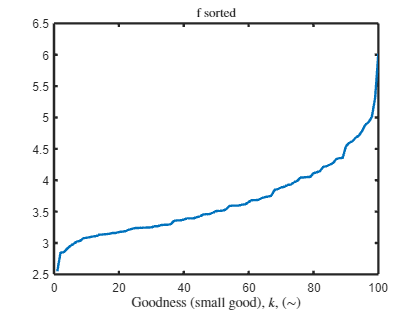



[f_sorted,ind] = sort(f_bests);
figure;
plot(f_bests(ind), "LineWidth",2); title("f sorted", "Interpreter","latex"); xlabel("Goodness (small good), $k$, $\left(\sim\right)$", "Interpreter","latex", "FontSize",12); set(gca, "LineWidth",2);

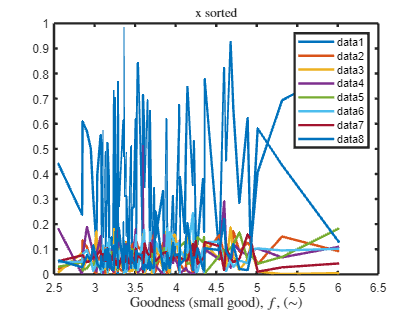

figure;
plot(f_bests(ind), x_bests(:,ind)', "LineWidth",2); title("x sorted", "Interpreter","latex"); xlabel("Goodness (small good), $f$, $\left(\sim\right)$", "Interpreter","latex", "FontSize",12); set(gca, "LineWidth",2); legend;

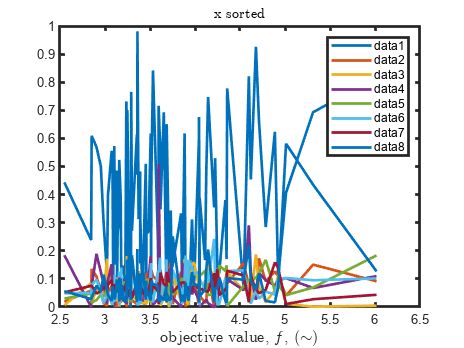

figure;
plot(f_bests(ind), x_bests(:,ind)', "LineWidth",2); title("x sorted", "Interpreter","latex"); xlabel("objective value, $f$, $\left(\sim\right)$", "Interpreter","latex", "FontSize",12); set(gca, "LineWidth",2); legend;

% function [f] = objective_function(x)
%     %f = x(1,:) * (sin(x(1,:)/100*(2*pi)).^2 + 1) .*x(2,:); % cost function
%     A = 10;
% %     f = A*size(x,2)
% %     for i = 1:length(x) 
% %         f = f + x(i).^2 - A * cos(2*pi*x(i));
% %     end
%     f = A*size(x,1)+ sum(x.^2 - A * cos(2*pi*x),1);
%     %c = [x(2,:), x(1,:)]/100; % const function gradient
%     %c = 100*[(x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500, (x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500];
% end


function[f] = objective_function(x)

%Side Lengths
% L2 = 3.07;
% L3 = 17.41;
% L4 = 5.52;
% L1 = sqrt((L4-L2)^2 + L3^2);

%f = L1*x(1) + L2*x(2) + L3*x(3) + L4*x(4) + x(5) + x(6) + x(7) + x(8); % Cost Function of Total Cross-Sectional Area [in^2]
f = wingbox_objective_function(x);

%c = [L1; L2; L3; L4; 1; 1; 1; 1]; % Patrial Derivative of f(x), c-Vector 


g = inequalConstraintFunction(x);
% g(g < 0) = 0;
f = f*1e0 + g*1e200;%+exp(sum(g)*1e13)

end

function [g,A] = inequalConstraintFunction(x)
% [time, tau_1, tau_2, tau_3, tau_4, sigma_1, sigma_2, sigma_3, sigma_4] = Stresses(x);
% 
% sigma_allow_t = 28000;  % Allowable Tensile Stress in psi
% sigma_allow_c = 20000;  % Allowable Compressive Stress in psi
% tau_allow_xy = 18000;   % Allowable Shear Stress in psi
% 
% % pt_tau_1 = q(1)/t1
% % pt_tau_2 = q(2)/t1
% % pt_tau_3 = q(3)/t1
% % pt_tau_4 = q(4)/t1 
% % pt_tau_5 = q(5)/t1
% % pt_tau_6 = q(6)/t2
% % pt_tau_7 = q(7)/t3
% % pt_tau_8 = q(8)/t3
% % pt_tau_9 = q(9)/t3
% % pt_tau_10 = q(10)/t4
% 
% % pt_tau = [pt_tau_1; pt_tau_2; pt_tau_3; pt_tau_4; pt_tau_5; pt_tau_6; pt_tau_7; pt_tau_8; pt_tau_9; pt_tau_10]
% % 
% % [~,temp] = max(abs(pt_tau(1:5)));
% % tau_1 = pt_tau(temp)
% % tau_2 = pt_tau(6)
% % [~,temp2] = max(abs(pt_tau(7:9)));
% % tau_3 = pt_tau(temp2)
% % tau_4 = pt_tau(10)
% 
% % Shear Stress Constraints
% g1 = tau_allow_xy/tau_1 - 1; % Top Skin Shear Stress Constraint (Side 1)
% g2 = tau_allow_xy/tau_2 - 1; % Aft Web Shear Stress Constraint (Side 2)
% g3 = tau_allow_xy/tau_3 - 1; % Bottom Skin Shear Stress Constraint (Side 3)
% g4 = tau_allow_xy/tau_4 - 1; % Fwd Web Shear Stress Constraint (Side 4)
% %g4=g4*1e3;
% % Normal Stress Constraints
% if sigma_1 > 0
%     g5 = sigma_allow_t/sigma_1 - 1; % Tensile Fwd Upper Spar Cap 1 Axial Stress Constraint (Point 1)
% else 
%     g5 = sigma_allow_c/sigma_1 - 1; % Compressive Fwd Upper Spar Cap 1 Axial Stress Constraint (Point 1)
% end
% 
% if sigma_2 > 0
%     g6 = sigma_allow_t/sigma_2 - 1; % Tensile Aft Upper Spar Cap 2 Axial Stress Constraint (Point 6)
% else 
%     g6 = sigma_allow_c/sigma_2 - 1; % Compressive Aft Upper Spar Cap 2 Axial Stress Constraint (Point 6)
% end
% 
% if sigma_3 > 0
%     g7 = sigma_allow_t/sigma_3 - 1; % Tensile Aft Lower Spar Cap 3 Axial Stress Constraint (Point 7)
% else 
%     g7 = sigma_allow_c/sigma_3 - 1; % Compressive Aft Lower Spar Cap 3 Axial Stress Constraint (Point 7)
% end
% 
% if sigma_4 > 0
%     g8 = sigma_allow_t/sigma_4 - 1; % Tensile Fwd Lower Spar Cap 4 Axial Stress Constraint (Point 10)
% else 
%     g8 = sigma_allow_c/sigma_4 - 1; % Compressive Fwd Lower Spar Cap 4 Axial Stress Constraint (Point 10)
% end
% 
% % Non-negativity Constraints of Design Variables
% g9 = -x(1)+ .00001;
% g10 = -x(2)+ .00001;
% g11 = -x(3)+ .00001;
% g12 = -x(4)+ .00001;
% g13 = -x(5)+ .00001;
% g14 = -x(6)+ .00001;
% g15 = -x(7)+ .00001;
% g16 = -x(8)+ .00001;
% 
% g = [g1; g2; g3; g4; g5; g6; g7; g8; g9; g10; g11; g12; g13; g14; g15; g16]; % Column Vector of All Inequality Constraints

g = wingbox_constraints(x);
% Partial Derivatives of the Inequality Constraints
% a1 = (g1(x(1) + 0.01*x(1)) - g1(x(1) - 0.01*x(1)))/(2*0.01*x(1))

% A = [a1; a2; a3; a4; a5; a6; a7; a8; a9; a10; a11; a12; a13; a14; a15; a16];

% for particle swarm
g = sum(g(g>0));
end

function [global_best, global_best_fitness] = particle_swarm_optimization(objective_function, number_of_dimentions, number_of_particles, max_iterations, inertia, c_1, c_2, x_lower, x_upper, nonnegative)
    positions = rand(number_of_dimentions, number_of_particles) .* (x_upper - x_lower) + x_lower; % initialise to random start locations (may want to scale beyond range 0,1)
    velocities = rand(number_of_dimentions, number_of_particles) * 1; % initialise to random start velocities (may want to scale beyond range 0,1)
    
    % positions = gpuArray(5 - rand(number_of_dimentions, number_of_particles) * 10); % initialise to random start locations (may want to scale beyond range 0,1)
    % velocities = gpuArray(rand(number_of_dimentions, number_of_particles)); % initialise to random start velocities (may want to scale beyond range 0,1)
    
    personal_best = positions; % the best known position of each particle is the current position
    global_best = positions(1,:); % the best known position of the swarm
    global_best_fitness = Inf; % the fitness value of the globally best position starts as Inf (unfit)
    
    
    % Create a grid of points for plotting contours
    % x_limits = [-5.12,5.12];
    % y_limits = [-5.12,5.12];
    % xSpace = linspace(x_limits(1), x_limits(2), 400);
    % ySpace = linspace(y_limits(1), y_limits(2), 400);
    % [X, Y] = meshgrid(xSpace, ySpace);
    % Z = arrayfun(@(x,y) objective_function([x;y]), X,Y); % Evaluate the objective function on the grid
    
    
    % Optimization loop
    for iteration = 1:max_iterations    
        % update particle fitness
        fitness = objective_function(positions); % compute current fitnesses
        personal_best_fitness = objective_function(personal_best); % compute personal best fitnesses
        
        
        personal_best(fitness < personal_best_fitness) = positions(fitness < personal_best_fitness); % update the personal bests of particles that have new personal bests
        [current_swarm_min, current_swarm_min_index] = min(fitness); % find the minimum of the current swarm
        
        if current_swarm_min < global_best_fitness % if the current minimum is less than the global minimum
            global_best = positions(:,current_swarm_min_index); % update the bolabl minimum position
            global_best_fitness = current_swarm_min; % update the globalminimum value
        end
        
        
        % Update Particle Velocity
        velocities = inertia * velocities +... % it wants to keep going in the direction it is moving
            c_1 * rand(number_of_dimentions, number_of_particles) .* (personal_best - positions) +... % it wants to keep move towards the best location it has seen
            c_2 * rand(number_of_dimentions, number_of_particles) .* (global_best - positions); % it wants to keep move towards the best location the swarm
        % Update Position
        positions = positions + velocities; % Update Position
        
        % Ensure positions are positive
        if nonnegative
            positions = max(positions, 0);
        end
        
        
        % Visualization
        %     clf;
        %     hold on;
        %     contourf(X, Y, Z, 50, "-", "EdgeColor","none"); % plot the contours of the function
        %     scatter(positions(1,:), positions(2,:), 'b'); % Particles
        %     scatter(global_best(1), global_best(2), 'r', 'filled'); % Global best
        %     title(['Iteration: ', num2str(iteration)]);
        %     xlabel('X');
        %     ylabel('Y');
        %     drawnow;
    end
end